% Low pass filter
clear;clc;close
load CMI_data.mat

t = reshape(CMI.t,900,1200);
p2 = reshape(CMI.p2,900,1200);
p3 = reshape(CMI.p3,900,1200);
p4 = reshape(CMI.p4,900,1200);
p6 = reshape(CMI.p6,900,1200);
p7 = reshape(CMI.p7,900,1200);
e7 = reshape(CMI.e7,900,1200);

Fourier transform and shift to negative->positive frequencies

t = t(:,322);
p2 = p2(:,322);
e7 = e7(:,322);
p2 = p2-nanmean(p2); % take  mean out to see variability
e7 = e7-nanmean(e7);

fp2 = fftshift(fft(p2));
fe7 = fftshift(fft(e7));

N = 900;
dt = 1;
fn= 1/(2*dt); % nyquist 
df = 1/(N*dt); % lowest
f = (-fn:df:fn-df)';

high pass filter

set low frequencies to zero, we're "passing" high frequencies through

kig = find(abs(f) <= 1/25& abs(f)>0);
fp2(kig) = 0;
fe7(kig) = 0;

fp2 = ifftshift(fp2); % inverse transport back
fe7 = ifftshift(fe7);

p2s = real(ifft(fp2)); % real part 
e7s = real(ifft(fe7));

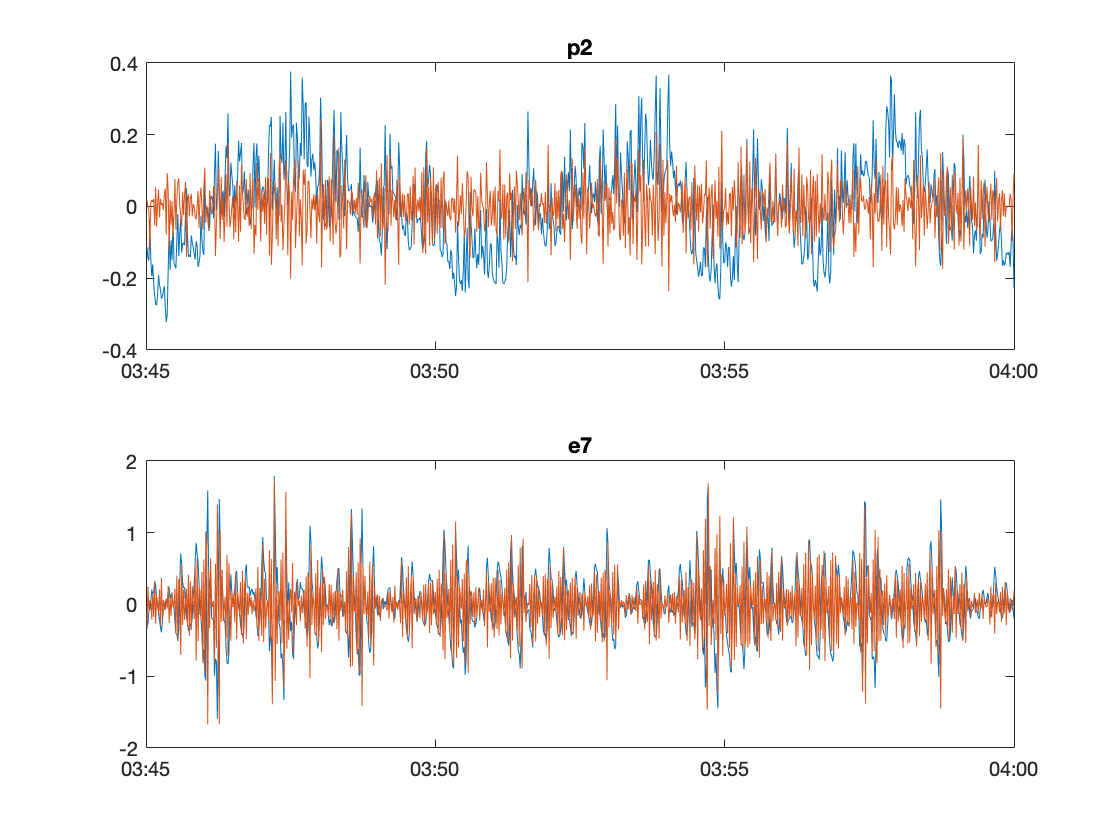

subplot(211)
plot(t,p2,t,p2s)
datetick
title('p2')
subplot(212)
plot(t,e7,t,e7s)
datetick
title('e7')

Low-pass filter

Just take all data - high pass to get low frequencies

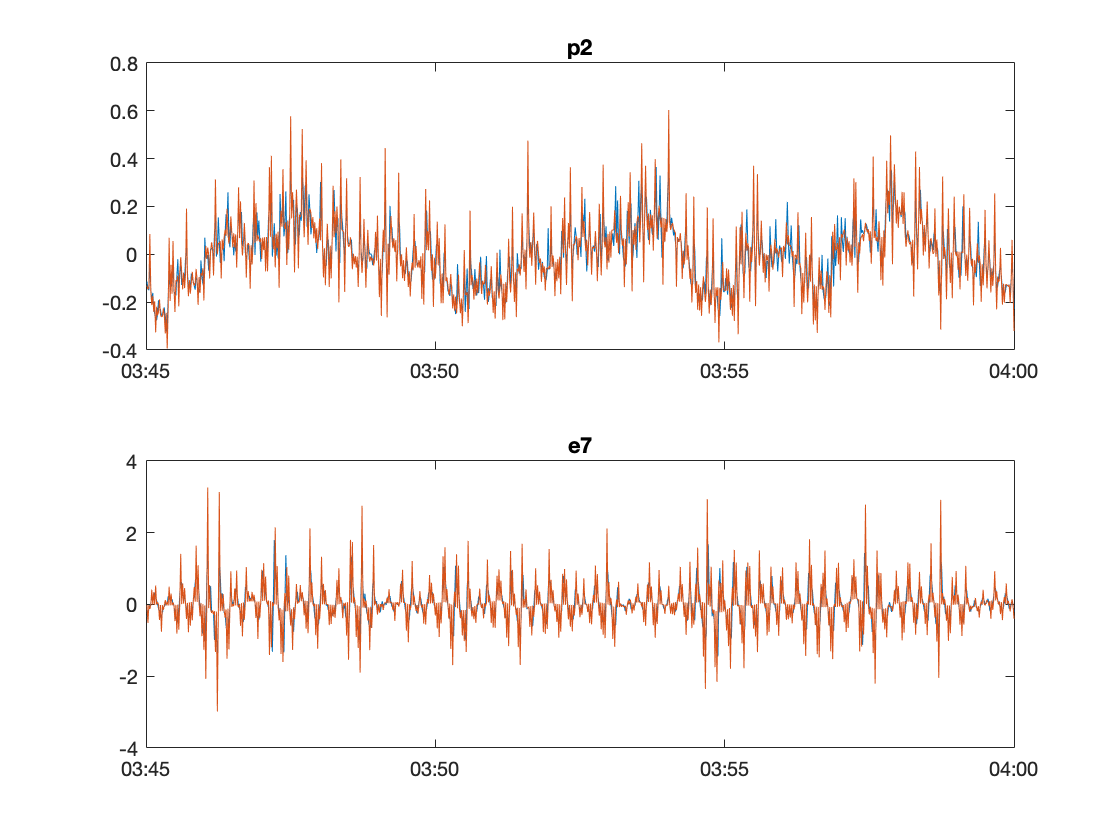

p2i = p2-p2s; % s version is high pass just take the "conjugate"
e7i = e7-e7s;
clf
subplot(211)
plot(t,p2,t,p2i)
datetick
title('p2')
subplot(212)
plot(t,e7,t,e7i)
datetick
title('e7')

Signal is very orange (the low passed frequencies) which makes sense.